# Демодуляция. Часть 3.

# Double Sideband Transmitted Carrier 

# (AM-DSB-TC)

**Для запуска скриптов необходимо корневую папку репозитория сделать рабочей папкой Matlab!**

### 1. Некогерентная демодуляция с помощью детектора огибающей

Рассмотрим некогерентный способ приема АМ-сигналов. Его преимуществом является простота, так как в этом случае не требуется восстанавливать несущую с точностью до фазы. Пусть при формировании АМ-сигнала выполняется условие:

$A_с \ge m_{\max }$,

где$A_с$- амплитуда несущей, а $m_{\max }$ - максимальное значение информационного сообщения. Тогда все сведения о сообщении содержатся в огибающей АМ-сигнала. Таким образом, некогерентный приемник представляет из себя просто детектор огибающей. Чтобы выделить огибающую, можно использовать нелинейное преобразование, а затем убрать лишние компоненты с помощью низкочастотного фильтра. В качестве нелинейного преобразования, например, можно взять вычисление абсолютного значения. Схема приемника при этом будет иметь вид:

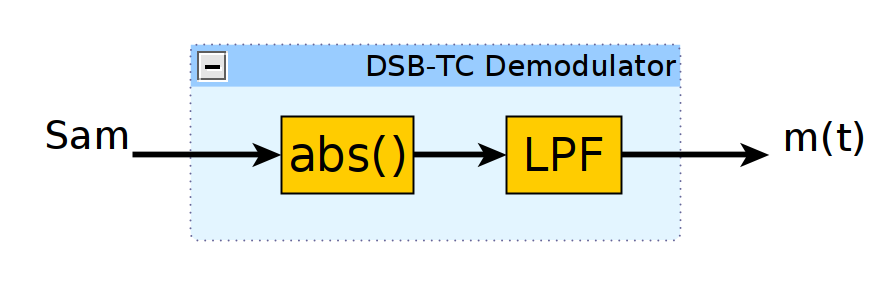

Рассмотрим, как работу такого приемника можо описать в аналитическим виде. Вычисление абсолютного значания приводит к тому, что участки сигнала, на которых он принимает отрицательные значания, изменяют свой знак на противоположный. Для простоты рассмотрим случай чисто гармонического сигнала. Операция взятия модуля  эквивалентна умножению на последовательность прямоугольных импульсов, значения которых равны 1, когда гармонический сигнал больше нуля, и равны -1, когда сигнал меньше нуля. Таким образом, прямоугольные импульсы на половине периода сигнала принимают значения, равные 1, а на другой половине -1. Период прямоугольных импульсов совпадает с периодом гармонического сигнала. 

 Пусть гармонический сигнал имеет вид:

$s_{\;\textrm{in}} =\textrm{Acos}\left(\omega_c t\right)$,

где $\omega_c$ - циклическая частота в рад/с. Сигнал из прямоугольных импульсов имеет тот же период, поэтому его можно разложить в ряд Фурье:


$$s_{\textrm{rect}} =A_0 +A_1 \cos \left(\omega_c t\right)+A_2 \cos \left(2\omega_c t\right)+A_3 \cos \left(3\omega_c t\right)+\cdots$$


Произведение АМ-сигнала и $s_{\mathrm{rect}}$ эквивалентно умножению АМ-сигнала на сумму ряда. В этом ряду есть слагаемое $A_1 \cos \left(\omega_c t\right)$, которое соответствует тону, частота которого совпадающает с частотой несущей. Остальные слагаемые ряда будет переносить информационный сигнал на другие частоты, кратные частоте несущей. Все побочные слагаемые в дальнейшем можно удалить с помощью фильтра нижних частот.

Ниже представлен скрипт, выполняющий некогерентный прием сигнала с амплитудной модуляцией. 

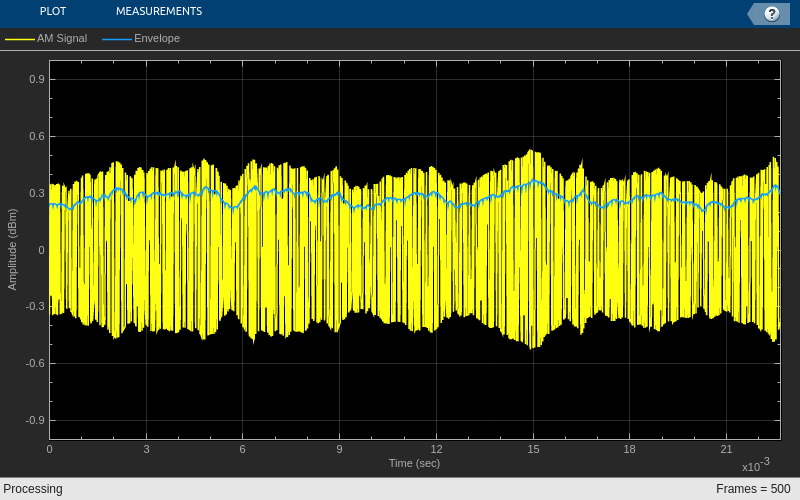

clc; clear; close all;
addpath('matlab/DSB_TC');

SignalFrameSize = 10000;  % количество отсчетов Ам-сигнала, получаемых за один раз
FramesNumber = 500;       % число обрабатываемых пачек данных
AudioAmp = 3;             % коэффициент усиления аудиосигнала
RateRatio = 10;           % коэффициент увеличения частоты дискретизации

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    'wav/Audio_DSB_TC.wav', ...
    'SamplesPerFrame',SignalFrameSize...
    );

% дополнительные расчеты
SignalFs = AudioReader.SampleRate;              % получаем частоту дискретизации модулированного сигнала
AudioFs = SignalFs / RateRatio;                 % частота дискретизации аудиосообщения

% рассчет коэффициентов фильтра нижних частот
H = Audio_Lowpass_FIR_Coeff();

% создание объекта для фильтрации
LowpassFIR = dsp.FIRFilter(H.Numerator);

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'YLimits', [-1, 1], ...
    'XLabel', 'Time (sec)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'AM Signal', 'Envelope'}, ...
    'SampleIncrement', 1/SignalFs ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов АМ-сигнала и выделение синфазного канала
    AmSignal = AudioReader();
    AmSignal = AmSignal(:,1);

    % вычисляем абсолютное значение отсчетов
    AbsAmSignal = abs(AmSignal);

    % фильтрация сигнала
    BasebandSignal = LowpassFIR(AbsAmSignal);

    % понижение частоты дискретизации
    Message = [Message; AudioAmp * DownSampler(BasebandSignal)];

    % вывод результатов на график
    Plotter([AmSignal BasebandSignal])

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.01)
end

Выше представлены временные диаграммы сигналов на входе (желтый) и выходе (синий) демодулятора. Можно увидеть, что сигнал на выходе совпадает с огибающей АМ-сигнала. 

% проигрывание полученного сообщения
sound(Message, AudioFs);

На слух можно сделать вывод, что аудиосообщение восстанавливается без явных искажений.

В файле *DSB_TC_Receiver_Part_3_1.slx* представлена Simulink модель некогерентного демодулятора, который ранее был реализован ввиде скрипта. 

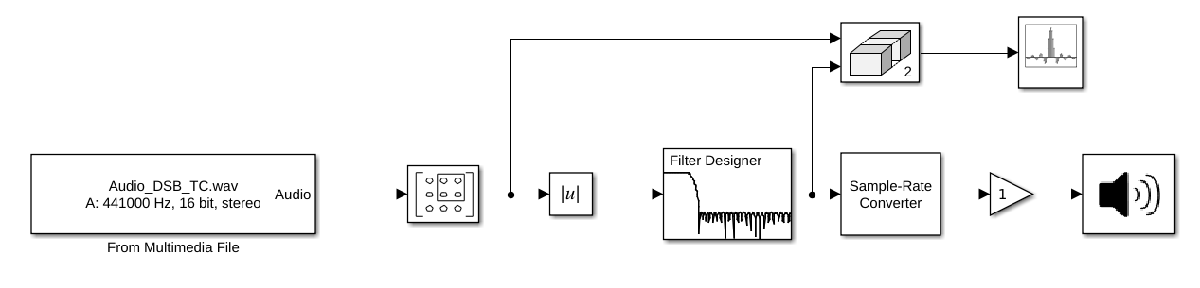 

### 2. Некогерентная демодуляция при квадратурном приеме

Рассмотрим как изменится структура некогерентного демодулятора в случае квадратурного приема. Сигнал теперь комплексный с односторонним спектром. Отличае от случая действительнго сигнала заключается в том, что теперь АМ-сигнал имеет вид:

 $s_{\textrm{am}} ={A\left(t\right)\cdot e}^{j\cdot \omega_с t}$. 

Если при формировании сигнала выполнено условие $A_с \ge m_{\max }$, то информационное сообщение можно восстановить из огибающей сигнала. Чтобы найти огибающую комплексного сигнала, достаточно вычислить его модуль. Схема приемника очень простая и представлена ниже:

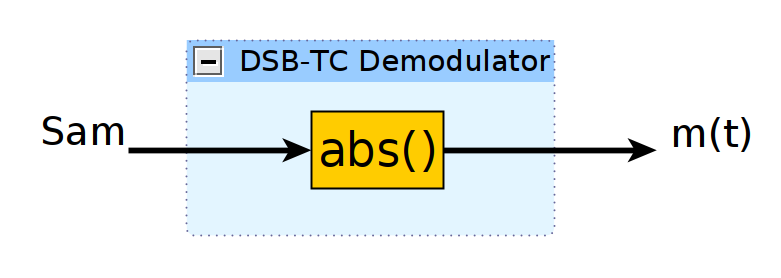

Ниже представлен скрипт, выполняющий некогерентный прием сигнала с амплитудной модуляцией. 

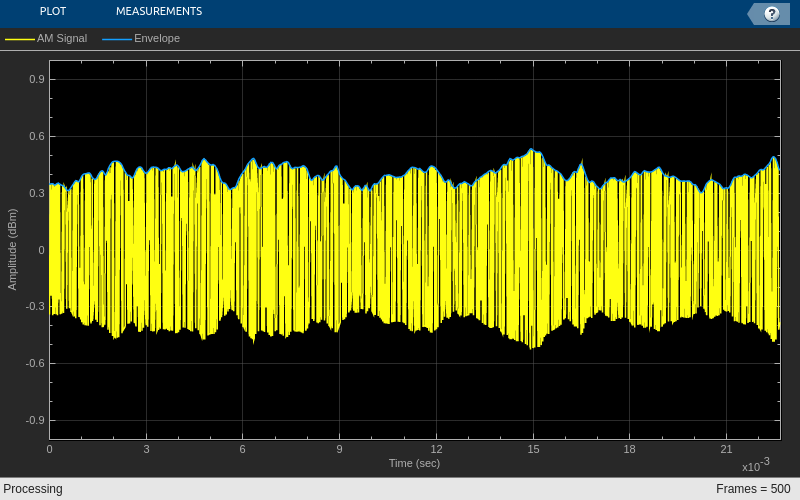

clc; clear; close all;

SignalFrameSize = 10000;  % количество отсчетов Ам-сигнала, получаемых за один раз
FramesNumber = 500;       % число обрабатываемых пачек данных
AudioAmp = 1;             % коэффициент усиления аудиосигнала
RateRatio = 10;           % коэффициент увеличения частоты дискретизации

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    'wav/Audio_DSB_TC.wav', ...
    'SamplesPerFrame',SignalFrameSize...
    );

% дополнительные расчеты
SignalFs = AudioReader.SampleRate;              % получаем частоту дискретизации модулированного сигнала
AudioFs = SignalFs / RateRatio;                 % частота дискретизации аудиосообщения

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'YLimits', [-1, 1], ...
    'XLabel', 'Time (sec)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'AM Signal', 'Envelope'}, ...
    'SampleIncrement', 1/SignalFs ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов АМ-сигнала и формирование комплексного сигнала
    AmSignal = AudioReader();
    AmSignal = AmSignal(:,1) + 1j*AmSignal(:,2);

    % вычисление амплитуды сигнала
    AbsAmSignal = abs(AmSignal);

    % понижение частоты дискретизации
    Message = [Message; AudioAmp*DownSampler(AbsAmSignal)];

    % вывод результатов на график
    Plotter([real(AmSignal) AbsAmSignal])

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.01)
end

Выше представлены временные диаграммы сигналов на входе (желтый, действительная составляющая) и выходе (синий) демодулятора. Можно увидеть, что сигнал на выходе фильтра совпадает с огибающей АМ-сигнала. 

% проигрывание полученного сообщения
sound(Message, AudioFs);

На слух можно сделать вывод, что аудиосообщение восстанавливается без явных искажений.

В файле *DSB_TC_Receiver_Part_3_2.slx* представлена Simulink модель когерентного демодулятора в квадратурном случае. 

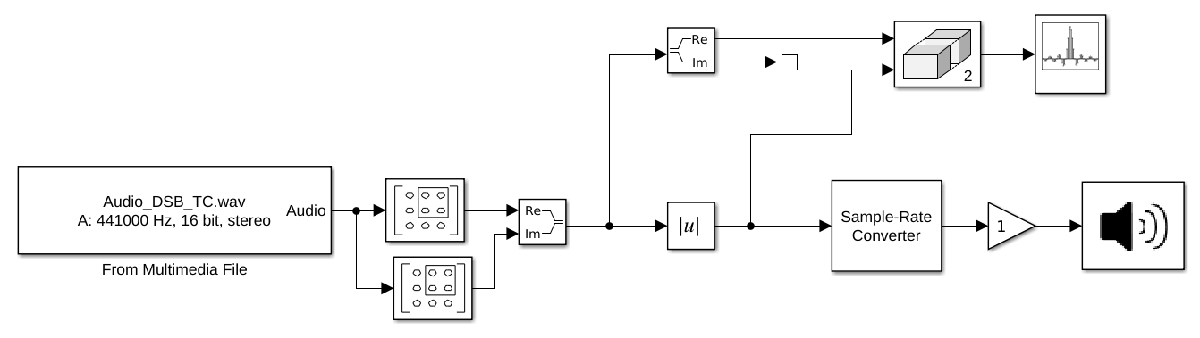

### Литература:

- B. P. Lathi Modern Digital and Analog Communication Systems

- R. Stewart, K. Barlee, D. Atkinson, L. Crockett Software Defined Radio using MATLAB® & Simulink and the RTL-SDR